Reading in data

clear
imread("data32\test\animal animal_faces cat cat_face\0BGPHALKEI6K.jpg", "jpg")

ans = 32×32×3 uint8 array
ans(:,:,1) =

   164   171   166   159   159   150   150   145   137   140   117    76    61    72    84    86    90    90    90    88    89    87    87    89    88    90    88    87    84    76    77    72
   170   172   169   158   159   155   150   143   140   141   116    75    59    71    83    86    87    88    89    88    90    92    92    88    90    93    92    86    84    82    79    71
   152   173   172   164   157   150   148   141   137   139   114    76    62    71    80    82    81    80    86    92    92    88    90    93    90    88    82    83    80    83    69    71
   150   172   165   160   156   151   146   142   136   140   116    76    62    72    79    82    80    80    85    89    90    95    95    87    85    88    81    80    76    72    72    70
   149   169   167   158   156   147   139   138   135   140   118    76    60    71    81    83    79    82    85    89    91    92    90    86    81    76    87   137   136    74    65  


imagefiles = dir("data32\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1661×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data32\test\animal animal_faces cat cat_face"

filepath = "data32\test\animal animal_faces cat cat_face"

for ii=1:200
   currentfilename = imagefiles(ii).name;
   currentimage = im2double(imread(filepath + "\" +  currentfilename));
   images{ii} = currentimage;
end

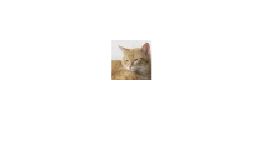

imshow(images{1})

Reproduce image

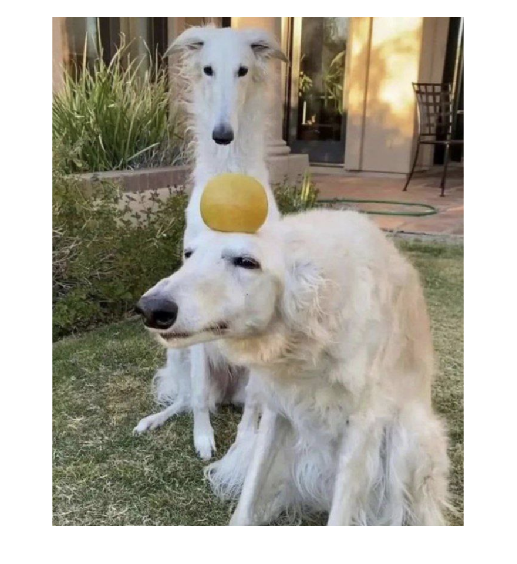

targetImage = im2double(imread("dogdogorange.png"));

imshow(targetImage)

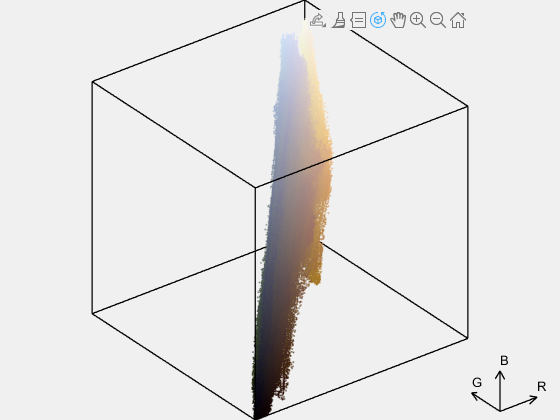

colorcloud(targetImage, "rgb");

clf

[l, h, d] = size(targetImage)

l = 867

h = 701

d = 3

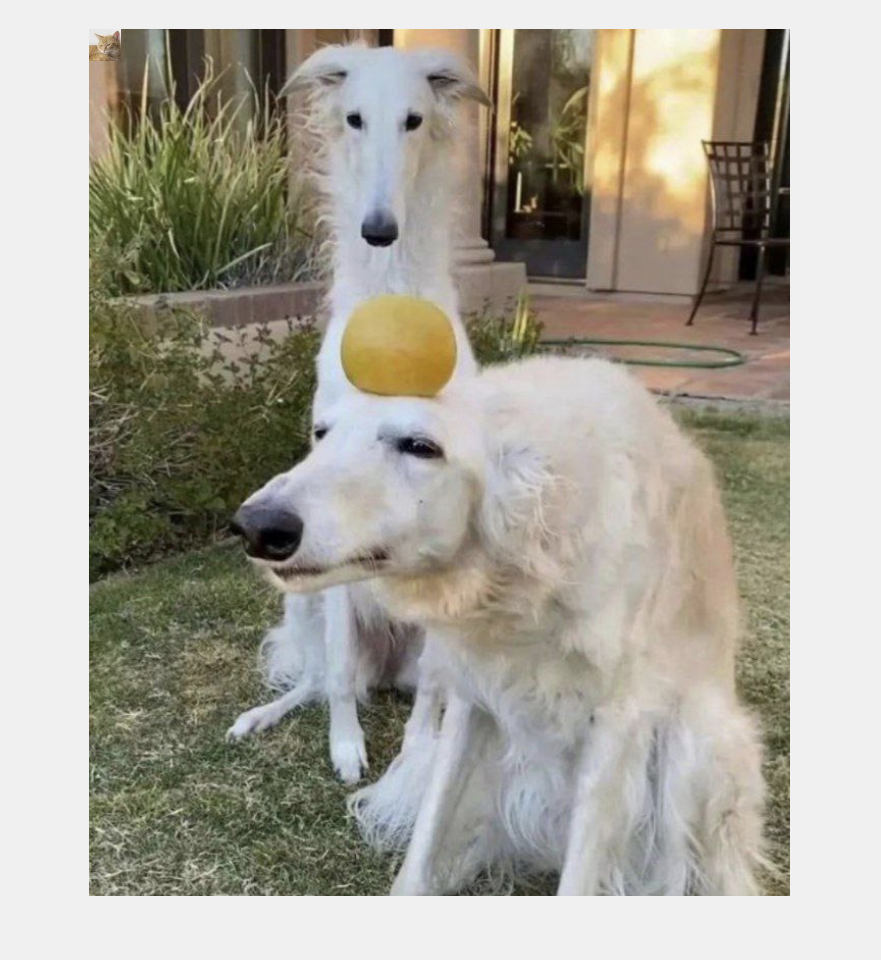


targetImage(1:32, 1:32, :) = images{1};

imshow(targetImage)

Image Segmentation

Use kmeans with random clustters to segment the image 

% segmentedImage = im2double(targetImage)
% for i = 1:3
% segmentedImage(:,:,i) = segmentImage(segmentedImage(:,:,i));
% end
% 
% imshow(segmentedImage)

load("xyz.mat")
load("illum.mat")
load("DLP.mat")
k = 100 ./ sum(xyz(:,2)' .* CIED65)

k = 4.6460


load("M_XYZ2RGB.mat")


Big Loop

rTileSize = 32;
oTileSize = 8;
%[~, datasetSize] = size(images)
[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 109

tileCols = ceil(cols / oTileSize)

tileCols = 88


outputImage = zeros(tileRows*rTileSize, tileCols * rTileSize,3);

%preprocess images by removing very similiar ones. Uses given threshold
%value
processedImages = preprocessImages(images, 12);

%clear("images") %jaja overwrite

[~, datasetSize] = size(processedImages)

datasetSize = 131

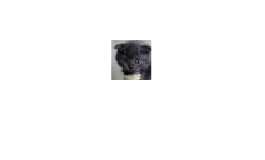


imshow(processedImages{2})

processedImages

processedImages = 1×131 cell array
    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {

processbar = waitbar(0, 'Processing Images...');
% go through each tile
for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        % convert current Tile to xyz, might use average colour
        averageTileXYZ = averageColourXYZ(currentTile);
       
        lowerDeltaEImages = {}; %holds index value to processed images
        similarityThreshold = 20; %how close the image has to be to get added to array above
        
        bestImageIndex = 0;
        bestDeltaE = 1000;

        waitbar(c/tileCols, processbar, "bonking kitties...");

        % find best image for each tile
        for i = 1:datasetSize
            
            curImg = processedImages{i};

            %colorcloud(targetImage, "rgb")
            % convert current sample image to xyz

            currentImageXYZ = averageColourXYZ(curImg);


            % use calcDeltaE
            [meanDeltaE, Max] = calcDeltaE(averageTileXYZ', currentImageXYZ');
            

            if Max < bestDeltaE
                bestDeltaE = Max;
                bestImageIndex = i;
                
                %add to subsample array for probing holds the index to
                %image array
                if Max < similarityThreshold

                    %currentTile(:,:,1);
                    lowerDeltaEImages{end+1} = i;
                end

            end
        end
        
        %Subsampling
        %subsample (4 or 9 samples recommended)
        subsamplesAmt = 9;
        
        subsampledTargetTile = subsampleImage(currentTile, subsamplesAmt);
        %subsampledTargetTileXYZ = averageColourXYZ(subsampledTargetTile);
        
        % till loop för att checka L skillnad i 3x3
        % calculate L values of 
        for q = 1:length(lowerDeltaEImages)
            subsampledCurrentImage = subsampleImage(processedImages{lowerDeltaEImages{q}}, subsamplesAmt);
            %subsampledCurrentImageXYZ = averageColourXYZ(subsampledCurrentImage);
            MSE = subsampledCmp(subsampledTargetTile, subsampledCurrentImage, subsamplesAmt)

        end
        

        tileRFrom = 1 + (r-1)*(rTileSize);
        tileRTo = r*rTileSize;
        tileCFrom = 1 + (c-1)*(rTileSize);
        tileCTo = c*rTileSize;
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = processedImages{bestImageIndex};
    end
end

distances = 756.0865

distances = 629.5538

distances = 216.7472

distances = 751.7706

distances = 201.0577

distances = 160.8176

distances = 167.4294

distances = 76.2879

distances = 218.7281

distances = 70.2437

distances = 451.6963

distances = 48.1012

distances = 18.9561

distances = 107.9471

distances = 207.7402

distances = 210.0896

distances = 207.8484

distances = 211.9789

distances = 207.1987

distances = 195.8142

distances = 224.7470

distances = 199.2459

distances = 208.2825

distances = 196.4167

distances = 183.0358

distances = 186.8599

distances = 232.8070

distances = 116.7938

distances = 219.1477

distances = 205.2791

distances = 280.3247

distances = 224.6188

distances = 409.2147

distances = 313.0499

distances = 173.4632

distances = 388.2758

distances = 389.0514

distances = 164.3168

distances = 572.6922

distances = 233.2395

distances = 60.3036

distances = 383.6135

distances = 283.7664

distances = 83.5779

distances = 411.7018

distances = 295.1740

distances = 50.0925

distances = 950.7725

distances = 327.3810

distances = 215.4501

distances = 801.7160

distances = 194.6706

distances = 170.1337

distances = 557.8848

distances = 291.3337

distances = 57.6407

distances = 632.6345

distances = 205.4482

distances = 65.7106

distances = 561.3508

distances = 228.8128

distances = 62.6078

distances = 718.8399

distances = 216.7226

distances = 134.8072

distances = 317.4442

distances = 532.5876

distances = 59.0946

distances = 148.9615

distances = 685.7648

distances = 310.2498

distances = 185.6420

distances = 70.7367

distances = 223.8337

distances = 271.3772

distances = 728.8696

distances = 211.2962

distances = 54.4754

distances = 668.6618

distances = 281.8441

distances = 214.6743

distances = 326.0530

distances = 222.7301

distances = 272.1437

distances = 713.5531

distances = 134.3630

distances = 308.4282

distances = 281.4202

distances = 257.9856

distances = 978.7397

distances = 315.2693

distances = 176.1933

distances = 127.0937

distances = 216.9684

distances = 180.2812

distances = 228.8744

distances = 993.3161

distances = 324.9300

distances = 187.5353

distances = 121.6828

distances = 175.5953

distances = 236.8194

distances = 148.4574

distances = 191.0175

distances = 139.1791

distances = 264.1587

distances = 232.3454

distances = 141.7247

distances = 140.9050

distances = 142.7305

distances = 1.1766e+03

distances = 373.2090

distances = 195.2980

distances = 197.6986

distances = 223.3747

distances = 248.5299

distances = 704.6575

distances = 276.2814

distances = 246.2439

distances = 91.4657

distances = 447.8673

distances = 281.0172

distances = 366.2418

distances = 771.5513

distances = 364.6830

distances = 205.3052

distances = 208.4229

distances = 143.5735

distances = 33.1424

distances = 239.9472

distances = 105.2545

distances = 358.6029

distances = 264.9019

distances = 200.6010

distances = 287.0436

distances = 323.9419

distances = 100.4903

distances = 349.2530

distances = 242.1832

distances = 204.7384

distances = 291.9824

distances = 324.9805

distances = 1.1649e+03

distances = 134.0532

distances = 264.8107

distances = 300.0844

distances = 213.2913

distances = 58.8130

distances = 388.5345

distances = 790.6042

distances = 233.8155

distances = 171.5908

distances = 284.0704

distances = 156.2002

distances = 392.5333

distances = 150.2011

distances = 1.6189e+03

distances = 139.4958

distances = 269.1528

distances = 398.0095

distances = 117.6338

distances = 674.0795

distances = 202.0768

distances = 163.1487

distances = 314.7338

distances = 348.7540

distances = 90.4758

distances = 553.1397

distances = 68.6098

distances = 180.3478

distances = 331.1811

distances = 60.8524

distances = 54.2369

distances = 440.4212

distances = 66.6352

distances = 348.2323

distances = 633.0018

distances = 177.2931

distances = 40.4678

distances = 682.1653

distances = 169.9331

distances = 199.6476

distances = 961.7334

distances = 304.6565

distances = 691.2984

distances = 393.8520

distances = 263.4152

distances = 429.1672

distances = 297.4887

distances = 473.3983

distances = 145.7535

distances = 248.9922

distances = 59.6254

distances = 326.7094

distances = 64.9135

distances = 754.3298

distances = 276.4547

distances = 152.6016

distances = 350.2633

distances = 241.0907

distances = 168.5129

distances = 329.2620

distances = 70.3526

distances = 467.4116

distances = 91.8685

distances = 321.6571

distances = 396.7021

distances = 78.6197

distances = 108.9233

distances = 122.7899

distances = 263.7184

distances = 493.7810

distances = 103.7317

distances = 72.9223

distances = 88.2397

distances = 304.3034

distances = 492.6875

distances = 104.2834

distances = 54.9562

distances = 241.3452

distances = 399.7709

distances = 80.4459

distances = 82.4853

distances = 26.6037

distances = 317.3307

distances = 539.2857

distances = 141.5910

distances = 45.2231

distances = 173.8394

distances = 364.2618

distances = 625.9234

distances = 172.2528

distances = 34.4880

distances = 210.6568

distances = 608.2435

distances = 170.9948

distances = 97.6531

distances = 127.6500

distances = 257.0080

distances = 519.3455

distances = 135.1663

distances = 65.9454

distances = 695.7159

distances = 49.7506

distances = 255.1154

distances = 215.9117

distances = 411.0247

distances = 471.5092

distances = 83.5853

distances = 90.1013

distances = 626.7090

distances = 53.1331

distances = 124.2802

distances = 241.5221

distances = 125.4330

distances = 321.6335

distances = 327.6045

distances = 252.8882

distances = 271.1634

distances = 199.2653

distances = 362.2757

distances = 148.8726

distances = 142.3247

distances = 280.7328

distances = 222.7000

distances = 319.1538

distances = 219.2707

distances = 228.0119

distances = 212.2935

distances = 646.7752

distances = 67.6367

distances = 73.9584

distances = 568.0816

distances = 422.3847

distances = 70.8137

distances = 193.3998

distances = 104.0652

distances = 577.9703

distances = 167.2578

distances = 32.4899

distances = 148.8543

distances = 253.1541

distances = 194.9156

distances = 537.2207

distances = 129.9975

distances = 24.6004

distances = 84.2010

distances = 210.9634

distances = 181.6876

distances = 64.9490

distances = 53.4168

distances = 233.1768

distances = 1.8980e+03

distances = 264.0057

distances = 238.8025

distances = 634.6633

distances = 186.9909

distances = 263.6195

distances = 379.7051

distances = 307.3689

distances = 213.3078

distances = 658.7141

distances = 184.7111

distances = 309.9415

distances = 264.8759

distances = 112.2661

distances = 197.9440

distances = 223.8984

distances = 115.8901

distances = 220.7389

distances = 268.0917

distances = 194.6449

distances = 193.9057

distances = 155.9896

distances = 360.0467

distances = 117.6672

distances = 243.1788

distances = 221.3569

distances = 294.0907

distances = 226.3278

distances = 221.1656

distances = 161.8001

distances = 453.7898

distances = 200.3071

distances = 284.7089

distances = 289.8096

distances = 248.9654

distances = 348.5004

distances = 838.2902

distances = 171.1251

distances = 337.4742

distances = 200.8473

distances = 313.8949

distances = 182.3705

distances = 215.8320

distances = 169.6393

distances = 969.4547

distances = 125.6580

distances = 372.9092

distances = 246.7128

distances = 247.2911

distances = 140.0438

distances = 174.0384

distances = 530.3698

distances = 317.6683

distances = 207.2871

distances = 382.5037

distances = 256.3883

distances = 254.6222

distances = 383.2186

distances = 272.4018

distances = 133.4601

distances = 421.4783

distances = 203.3191

distances = 242.4868

distances = 232.6749

distances = 223.1676

distances = 259.0276

distances = 275.1888

distances = 200.5929

distances = 1.2138e+03

distances = 164.9268

distances = 475.2543

distances = 211.9100

distances = 172.8474

distances = 159.2271

distances = 196.0658

distances = 897.9516

distances = 119.2168

distances = 405.8981

distances = 376.3641

distances = 387.5455

distances = 213.9511

distances = 492.0203

distances = 365.8007

distances = 307.1827

distances = 446.5479

distances = 225.4587

distances = 689.6694

distances = 385.3718

distances = 252.9831

distances = 286.3937

distances = 170.2525

distances = 201.8319

distances = 1.1270e+03

distances = 133.8757

distances = 420.0452

distances = 241.2399

distances = 208.4790

distances = 258.1725

distances = 199.1445

distances = 298.4432

distances = 188.0435

distances = 570.8141

distances = 234.5986

distances = 332.8752

distances = 463.3873

distances = 326.0962

distances = 235.1378

distances = 573.6446

distances = 420.7251

distances = 291.0089

distances = 425.6880

distances = 214.9925

distances = 368.8145

distances = 246.6710

distances = 675.8869

distances = 186.2515

distances = 330.3768

distances = 300.3119

distances = 222.1659

distances = 133.6930

distances = 167.1706

distances = 505.9061

distances = 348.6627

distances = 568.4441

distances = 218.6184

distances = 221.4815

distances = 182.9545

distances = 367.7583

distances = 1.0294e+03

distances = 111.3354

distances = 355.2736

distances = 223.2184

distances = 232.4446

distances = 173.4543

distances = 956.1815

distances = 260.2419

distances = 240.5281

distances = 114.6942

distances = 78.8093

distances = 104.5009

distances = 232.7159

distances = 196.7389

distances = 130.3518

distances = 889.3515

distances = 238.5105

distances = 309.9172

distances = 126.5504

distances = 162.7426

distances = 145.2113

distances = 157.3804

distances = 111.0845

distances = 636.3514

distances = 226.1421

distances = 298.4574

distances = 290.0771

distances = 136.2076

distances = 220.8820

distances = 186.4733

distances = 1.1186e+03

distances = 128.5668

distances = 318.2181

distances = 215.4881

distances = 117.1413

distances = 169.0618

distances = 245.7869

distances = 545.5003

distances = 438.3940

distances = 407.5626

distances = 173.7716

distances = 158.0856

distances = 530.7427

distances = 471.8341

distances = 214.9276

distances = 346.2547

distances = 360.9246

distances = 446.0832

distances = 257.1346

distances = 738.2236

distances = 237.5463

distances = 382.9483

distances = 234.4427

distances = 158.7545

distances = 226.9954

distances = 251.3910

distances = 182.7183

distances = 458.1632

distances = 480.2868

distances = 295.9764

distances = 310.6218

distances = 276.3280

distances = 356.2294

distances = 371.8593

distances = 138.5827

distances = 199.5407

distances = 360.5158

distances = 348.3954

distances = 502.0775

distances = 318.9490

distances = 226.3047

distances = 194.5975

distances = 470.1741

distances = 324.8397

distances = 298.3806

distances = 449.3243

distances = 298.8183

distances = 303.6509

distances = 747.9134

distances = 260.9332

distances = 216.3975

distances = 262.1517

distances = 122.4490

distances = 135.3733

distances = 230.5907

distances = 171.8040

distances = 316.6632

distances = 1.0018e+03

distances = 106.4736

distances = 285.1616

distances = 234.5050

distances = 121.9741

distances = 268.7363

distances = 149.7060

distances = 191.8927

distances = 65.1112

distances = 841.4118

distances = 225.0004

distances = 153.5973

distances = 123.4650

distances = 190.9831

distances = 222.1115

distances = 146.8264

distances = 165.5728

distances = 178.1528

distances = 228.4787

distances = 149.7255

distances = 477.8838

distances = 553.2363

distances = 505.7265

distances = 583.6833

distances = 292.2246

distances = 454.3640

distances = 378.7742

distances = 312.4345

distances = 167.7016

distances = 473.4729

distances = 312.1572

distances = 292.2637

distances = 256.6486

distances = 616.0793

distances = 287.0357

distances = 283.3783

distances = 440.1605

distances = 156.1433

distances = 266.9843

distances = 283.3139

distances = 417.5878

distances = 790.3078

distances = 170.9974

distances = 224.2798

distances = 233.3971

distances = 198.9918

distances = 301.2976

distances = 227.7747

distances = 211.3250

distances = 192.7925

distances = 534.4296

distances = 508.9085

distances = 466.8349

distances = 550.3110

distances = 561.0428

distances = 330.3210

distances = 198.9627

distances = 162.0960

distances = 252.6533

distances = 133.5494

distances = 100.0122

distances = 172.5578

distances = 413.9839

distances = 382.8038

distances = 375.9962

distances = 325.5635

distances = 392.8754

distances = 149.4799

distances = 240.6100

distances = 753.6496

distances = 208.1720

distances = 284.6240

distances = 753.6791

distances = 298.3120

distances = 352.0193

distances = 261.7265

distances = 213.2271

distances = 147.8724

distances = 201.4075

distances = 210.7698

distances = 203.8338

distances = 371.8078

distances = 201.8745

distances = 201.8449

distances = 230.0050

distances = 210.6890

distances = 206.3676

distances = 224.0828

distances = 198.9199

distances = 195.2626

distances = 247.1407

distances = 52.7989

distances = 218.2358

distances = 318.4804

distances = 56.3241

distances = 460.9826

distances = 262.1810

distances = 193.8524

distances = 46.6185

distances = 88.6975

distances = 129.0128

distances = 197.7315

distances = 319.7879

distances = 388.4311

distances = 153.7613

distances = 553.0349

distances = 213.7134

distances = 74.1188

distances = 635.5982

distances = 157.6654

distances = 78.5763

distances = 473.0816

distances = 296.8229

distances = 43.8613

distances = 662.0166

distances = 283.1059

distances = 97.8138

distances = 301.3878

distances = 34.7447

distances = 275.2246

distances = 215.5945

distances = 367.4014

distances = 310.8858

distances = 92.1676

distances = 363.4668

distances = 337.3379

distances = 117.2760

distances = 210.4385

distances = 351.2582

distances = 444.8916

distances = 73.0120

distances = 579.6001

distances = 104.7525

distances = 539.1572

distances = 219.8117

distances = 43.6006

distances = 236.2758

distances = 323.2145

distances = 777.0383

distances = 251.5237

distances = 191.2535

distances = 44.7126

distances = 224.4897

distances = 286.3638

distances = 601.4731

distances = 245.0665

distances = 78.9288

distances = 300.1140

distances = 555.5460

distances = 251.4850

distances = 59.9116

distances = 424.9767

distances = 751.8851

distances = 388.2699

distances = 243.6546

distances = 106.9487

distances = 281.2076

distances = 145.9167

distances = 268.7567

distances = 607.8610

distances = 169.1794

distances = 344.4610

distances = 254.6523

distances = 253.9804

distances = 168.3743

distances = 676.1511

distances = 209.1966

distances = 363.9777

distances = 486.2591

distances = 332.9604

distances = 480.6324

distances = 651.0934

distances = 325.2244

distances = 206.2156

distances = 87.3427

distances = 271.9288

distances = 180.3980

distances = 250.6022

distances = 216.6784

distances = 221.0113

distances = 248.2186

distances = 197.1888

distances = 224.3528

distances = 165.6486

distances = 79.7670

distances = 652.7382

distances = 246.4015

distances = 40.2928

distances = 346.5052

distances = 654.3197

distances = 320.2786

distances = 383.8951

distances = 590.0608

distances = 568.5257

distances = 884.4205

distances = 140.2737

distances = 225.5917

distances = 253.7951

distances = 380.5988

distances = 454.0198

distances = 241.0646

distances = 553.3514

distances = 211.9934

distances = 544.7231

distances = 309.4607

distances = 117.2505

distances = 312.0163

distances = 274.4525

distances = 381.6482

distances = 31.4833

distances = 411.8464

distances = 335.1944

distances = 1.3247e+03

distances = 143.3363

distances = 326.9970

distances = 209.8352

distances = 216.9136

distances = 207.1598

distances = 279.6967

distances = 750.6847

distances = 457.5881

distances = 401.7615

distances = 606.1257

distances = 432.5358

distances = 425.8474

distances = 153.3206

distances = 789.1245

distances = 244.1434

distances = 266.2158

distances = 227.6895

distances = 75.3067

distances = 99.9341

distances = 153.8378

distances = 297.7613

distances = 634.5600

distances = 453.4042

distances = 64.4843

distances = 63.2491

distances = 460.0140

distances = 74.4441

distances = 96.9962

distances = 175.3282

distances = 228.9306

distances = 414.6612

distances = 135.5684

distances = 272.8365

distances = 706.6064

distances = 104.6297

distances = 45.3462

distances = 168.5582

distances = 312.7305

distances = 352.3797

distances = 251.1489

distances = 523.7428

distances = 161.7343

distances = 905.1887

distances = 141.0786

distances = 241.4043

distances = 182.7027

distances = 138.4506

distances = 487.8339

distances = 72.8918

distances = 158.1389

distances = 473.5045

distances = 324.4038

distances = 464.1100

distances = 58.4769

distances = 98.0933

distances = 966.1181

distances = 164.2683

distances = 192.6273

distances = 338.1966

distances = 608.5649

distances = 149.9637

distances = 698.2018

distances = 193.9112

distances = 190.9542

distances = 294.7679

distances = 48.8937

distances = 86.6258

distances = 47.7042

distances = 406.6636

distances = 731.6777

distances = 252.8739

distances = 49.7321

distances = 47.7332

distances = 353.8116

distances = 789.7794

distances = 352.9602

distances = 1.0781e+03

distances = 314.4227

distances = 561.6393

distances = 618.7500

distances = 281.5839

distances = 140.4388

distances = 63.1007

distances = 299.7126

distances = 567.7602

distances = 144.8133

distances = 45.2958

distances = 437.2019

distances = 750.8026

distances = 192.6210

distances = 55.6693

distances = 241.7018

distances = 197.8519

distances = 351.2577

distances = 405.1649

distances = 321.2956

distances = 325.2158

distances = 56.9795

distances = 95.1822

distances = 423.9971

distances = 168.8624

distances = 155.5929

distances = 209.5243

distances = 283.8900

distances = 271.5018

distances = 241.9231

distances = 303.7442

distances = 227.1779

distances = 374.5861

distances = 478.8779

distances = 554.5745

distances = 437.8261

distances = 405.1949

distances = 372.0857

distances = 127.1065

distances = 391.1779

distances = 131.9172

distances = 266.1300

distances = 339.2412

distances = 301.4302

distances = 277.5022

distances = 291.1523

distances = 209.0257

distances = 339.0473

distances = 214.9585

distances = 108.9640

distances = 258.6761

distances = 201.8511

distances = 287.2781

distances = 224.7495

distances = 188.1516

distances = 184.1914

distances = 323.3186

distances = 568.1661

distances = 450.2028

distances = 73.5555

distances = 59.6257

distances = 451.8809

distances = 503.5874

distances = 478.4547

distances = 87.8997

distances = 216.7414

distances = 84.7575

distances = 535.2128

distances = 141.1074

distances = 45.4876

distances = 200.4999

distances = 176.0173

distances = 312.0681

distances = 437.0714

distances = 585.7918

distances = 183.3786

distances = 20.1935

distances = 778.7211

distances = 125.3000

distances = 314.0781

distances = 814.0156

distances = 225.8498

distances = 292.3346

distances = 166.0805

distances = 70.1842

distances = 147.3827

distances = 217.4252

distances = 147.0529

distances = 1.0581e+03

distances = 112.5682

distances = 378.5711

distances = 224.0910

distances = 276.4026

distances = 185.8383

distances = 155.0080

distances = 170.0858

distances = 398.2809

distances = 182.0208

distances = 149.4301

distances = 284.1053

distances = 212.4407

distances = 246.2208

distances = 214.7072

distances = 385.4139

distances = 392.1326

distances = 358.9525

distances = 299.6725

distances = 273.9953

distances = 258.8282

distances = 409.6368

distances = 109.8869

distances = 817.1282

distances = 251.5121

distances = 150.2557

distances = 72.5408

distances = 315.1364

distances = 192.1427

distances = 291.0226

distances = 195.3786

distances = 1.0888e+03

distances = 143.5408

distances = 440.9930

distances = 232.2276

distances = 285.1659

distances = 188.4305

distances = 211.3639

distances = 184.0389

distances = 84.4971

distances = 390.5449

distances = 334.6524

distances = 178.0425

distances = 410.0006

distances = 265.7419

distances = 148.3627

distances = 154.4354

distances = 146.7597

distances = 393.6312

distances = 230.8084

distances = 324.5592

distances = 193.4581

distances = 222.7061

distances = 184.0332

distances = 147.4544

distances = 407.5093

distances = 191.3706

distances = 240.2168

distances = 196.7961

distances = 170.3017

distances = 248.4424

distances = 235.5954

distances = 164.9195

distances = 738.2625

distances = 340.3321

distances = 179.3572

distances = 302.5032

distances = 262.8976

distances = 668.7393

distances = 184.6970

distances = 246.8626

distances = 234.2198

distances = 322.0596

distances = 326.3185

distances = 56.5369

distances = 84.2416

distances = 189.7373

distances = 629.8303

distances = 387.9011

distances = 194.5768

distances = 243.0761

distances = 218.2593

distances = 274.3147

distances = 646.0240

distances = 335.0472

distances = 199.5654

distances = 410.3622

distances = 234.7646

distances = 905.2769

distances = 290.3676

distances = 178.8283

distances = 117.8441

distances = 203.0649

distances = 131.8337

distances = 207.1777

distances = 149.0972

distances = 644.5590

distances = 241.8566

distances = 358.1861

distances = 224.3786

distances = 71.5825

distances = 364.0026

distances = 220.2200

distances = 314.2793

distances = 241.4312

distances = 987.6376

distances = 276.4722

distances = 156.8472

distances = 94.4441

distances = 286.0148

distances = 215.0216

distances = 153.4256

distances = 412.9447

distances = 275.0354

distances = 501.7931

distances = 396.1879

distances = 329.1199

distances = 219.3162

distances = 141.6624

distances = 409.0155

distances = 327.8952

distances = 339.8365

distances = 499.6913

distances = 475.4027

distances = 326.2424

distances = 229.2492

distances = 143.2031

distances = 808.3924

distances = 139.6726

distances = 227.6607

distances = 244.4645

distances = 415.5218

distances = 248.6334

distances = 522.3291

distances = 306.8752

distances = 372.5262

distances = 206.6283

distances = 512.7304

distances = 315.8608

distances = 246.0367

distances = 291.3020

distances = 792.9577

distances = 377.8291

distances = 429.7878

distances = 118.6326

distances = 141.7043

distances = 250.8783

distances = 178.3805

distances = 1.0734e+03

distances = 176.7735

distances = 374.1955

distances = 142.5404

distances = 152.2899

distances = 118.1208

distances = 191.1078

distances = 158.3413

distances = 92.3391

distances = 986.4859

distances = 123.0226

distances = 306.4534

distances = 211.1021

distances = 88.0216

distances = 150.1917

distances = 175.5180

distances = 103.7556

distances = 597.3591

distances = 306.9438

distances = 278.0935

distances = 284.5530

distances = 275.2187

distances = 294.7807

distances = 215.5897

distances = 100.6509

distances = 418.7752

distances = 384.0334

distances = 400.6642

distances = 476.4706

distances = 475.9500

distances = 407.4728

distances = 768.0103

distances = 384.6451

distances = 353.3393

distances = 249.1153

distances = 98.5124

distances = 165.4339

distances = 145.0446

distances = 984.3075

distances = 183.1803

distances = 98.8289

distances = 140.6318

distances = 218.1984

distances = 78.7893

distances = 180.7183

distances = 166.4498

distances = 115.0050

distances = 256.3084

distances = 449.7145

distances = 662.8760

distances = 472.4065

distances = 300.8996

distances = 331.2020

distances = 627.8218

distances = 415.2711

distances = 265.2495

distances = 335.6623

distances = 267.0667

distances = 316.7315

distances = 547.9691

distances = 197.9045

distances = 344.1895

distances = 397.5713

distances = 295.0617

distances = 212.2388

distances = 129.3410

distances = 276.5521

distances = 363.9281

distances = 303.3678

distances = 285.8631

distances = 244.5428

distances = 288.7665

distances = 219.5911

distances = 136.5631

distances = 122.0352

distances = 151.2665

distances = 310.8595

distances = 353.7294

distances = 277.5001

distances = 279.3837

distances = 450.7720

distances = 604.0468

distances = 512.3507

distances = 268.2159

distances = 454.9567

distances = 212.3562

distances = 383.6148

distances = 733.2015

distances = 269.7924

distances = 172.2805

distances = 113.5208

distances = 159.8855

distances = 180.9613

distances = 149.6372

distances = 135.8788

distances = 137.1355

distances = 447.5318

distances = 186.1479

distances = 154.4927

distances = 414.5369

distances = 168.6410

distances = 361.0603

distances = 192.0899

distances = 855.4907

distances = 253.6272

distances = 188.3938

distances = 76.8369

distances = 547.9891

distances = 395.9745

distances = 236.5297

distances = 170.5822

distances = 246.1149

distances = 252.7695

distances = 111.0090

distances = 151.0375

distances = 749.0660

distances = 196.8275

distances = 229.7322

distances = 170.3480

distances = 140.4500

distances = 229.8577

distances = 264.6701

distances = 347.9408

distances = 396.1159

distances = 193.7744

distances = 494.4331

distances = 396.4365

distances = 203.4202

distances = 199.5466

distances = 526.0016

distances = 214.0926

distances = 375.8441

distances = 124.4769

distances = 288.2604

distances = 155.4851

distances = 150.9122

distances = 41.9516

distances = 345.9182

distances = 177.4326

distances = 229.4497

distances = 123.1452

distances = 282.9116

distances = 65.2689

distances = 194.9045

distances = 142.9637

distances = 44.2277

distances = 333.8360

distances = 242.8546

distances = 280.2398

distances = 99.1054

distances = 141.6244

distances = 46.8391

distances = 252.2279

distances = 38.1357

distances = 417.3399

distances = 192.6474

distances = 194.4881

distances = 46.2139

distances = 58.2540

distances = 283.0138

distances = 536.8042

distances = 145.4532

distances = 186.4330

distances = 142.8446

distances = 474.4038

distances = 232.3853

distances = 255.9095

distances = 269.7158

distances = 57.3602

distances = 493.2832

distances = 107.8942

distances = 186.9258

distances = 413.7910

distances = 84.0315

distances = 240.7691

distances = 250.7469

distances = 362.1584

distances = 81.7781

distances = 589.3491

distances = 92.5807

distances = 188.2829

distances = 772.9971

distances = 312.1253

distances = 148.1710

distances = 395.8676

distances = 104.2478

distances = 237.8302

distances = 364.7955

distances = 63.2668

distances = 231.8553

distances = 315.1141

distances = 177.1007

distances = 99.6327

distances = 262.7933

distances = 138.3171

distances = 270.6738

distances = 190.2418

distances = 246.5138

distances = 271.8627

distances = 44.8394

distances = 178.0755

distances = 107.5152

distances = 398.3866

distances = 252.6779

distances = 190.7519

distances = 835.6085

distances = 208.2428

distances = 157.5463

distances = 177.0184

distances = 147.6008

distances = 244.4777

distances = 62.3456

distances = 283.2584

distances = 167.5613

distances = 699.9887

distances = 207.1001

distances = 93.0606

distances = 670.0753

distances = 370.5154

distances = 319.8316

distances = 115.1378

distances = 392.2811

distances = 375.9269

distances = 341.3978

distances = 156.5982

distances = 423.4325

distances = 427.7409

distances = 620.1031

distances = 267.1702

distances = 225.5661

distances = 15.4283

distances = 497.0589

distances = 305.5979

distances = 370.6778

distances = 870.2069

distances = 137.9536

distances = 336.8454

distances = 211.4783

distances = 90.0487

distances = 300.0815

distances = 201.3495

distances = 284.2226

distances = 164.7425

distances = 98.9810

distances = 434.1195

distances = 273.6903

distances = 228.7572

distances = 292.0618

distances = 220.8486

distances = 343.7752

distances = 170.9957

distances = 730.0806

distances = 219.6657

distances = 271.1966

distances = 198.4795

distances = 67.1378

distances = 333.9395

distances = 259.0759

distances = 303.9326

distances = 235.4856

distances = 153.8935

distances = 422.8051

distances = 224.1133

distances = 164.1987

distances = 259.4261

distances = 171.2185

distances = 274.6389

distances = 188.8029

distances = 80.2987

distances = 393.8404

distances = 272.3702

distances = 436.8181

distances = 417.1498

distances = 174.7745

distances = 529.1322

distances = 243.5696

distances = 248.2944

distances = 989.3647

distances = 316.5706

distances = 179.0213

distances = 126.7740

distances = 252.0505

distances = 169.9124

distances = 233.9149

distances = 155.8036

distances = 594.0474

distances = 408.7281

distances = 317.1082

distances = 687.1013

distances = 226.0189

distances = 178.5362

distances = 314.4490

distances = 224.1709

distances = 508.7299

distances = 120.0857

distances = 354.0098

distances = 206.0910

distances = 168.6869

distances = 291.6238

distances = 291.8218

distances = 725.6953

distances = 355.0166

distances = 214.4253

distances = 74.7777

distances = 274.2400

distances = 225.5952

distances = 94.0891

distances = 331.9975

distances = 305.4737

distances = 415.0227

distances = 316.4694

distances = 465.3250

distances = 232.3353

distances = 133.9537

distances = 467.8635

distances = 266.3959

distances = 290.5466

distances = 225.5729

distances = 230.3329

distances = 290.9728

distances = 211.9782

distances = 364.1254

distances = 112.7107

distances = 311.8648

distances = 432.0877

distances = 71.0218

distances = 381.4927

distances = 385.5720

distances = 499.1421

distances = 350.7346

distances = 336.6176

distances = 99.8831

distances = 66.9562

distances = 371.0011

distances = 404.2765

distances = 55.4551

distances = 261.7719

distances = 193.7370

distances = 279.4665

distances = 389.9412

distances = 82.3277

distances = 440.3185

distances = 191.7689

distances = 342.6432

distances = 245.8028

distances = 177.3556

distances = 133.7578

distances = 473.0582

distances = 683.9256

distances = 230.5913

distances = 427.8760

distances = 432.4331

distances = 642.3720

distances = 374.6347

distances = 552.7180

distances = 115.5679

distances = 300.8276

distances = 297.0457

distances = 520.8098

distances = 136.8308

distances = 260.4195

distances = 91.0139

distances = 47.7901

distances = 155.9938

distances = 340.1246

distances = 285.1130

distances = 351.2827

distances = 465.3157

distances = 44.6682

distances = 59.5847

distances = 805.4483

distances = 200.1020

distances = 305.4250

distances = 189.0700

distances = 79.7926

distances = 158.1546

distances = 111.0926

distances = 151.1919

distances = 149.2470

distances = 418.3754

distances = 197.0199

distances = 252.4960

distances = 316.1222

distances = 160.1673

distances = 462.6895

distances = 209.3876

distances = 124.9366

distances = 1.3547e+03

distances = 203.2032

distances = 141.6695

distances = 450.7523

distances = 126.6690

distances = 132.8150

distances = 1.4392e+03

distances = 221.2009

distances = 182.8943

distances = 408.0675

distances = 240.0120

distances = 83.2459

distances = 211.3218

distances = 424.8776

distances = 64.6935

distances = 190.8575

distances = 280.0062

distances = 387.7416

distances = 102.6211

distances = 347.4467

distances = 512.4735

distances = 76.8367

distances = 66.0496

distances = 143.3059

distances = 214.0837

distances = 392.2369

distances = 106.6520

distances = 70.2431

distances = 72.2247

distances = 162.3055

distances = 445.5255

distances = 479.6981

distances = 192.3238

distances = 224.6426

distances = 514.8983

distances = 237.4198

distances = 97.8794

distances = 133.0131

distances = 170.8918

distances = 221.8378

distances = 29.0403

distances = 284.5804

distances = 66.8007

distances = 69.4085

distances = 94.5910

distances = 181.7322

distances = 375.3899

distances = 371.3663

distances = 288.2570

distances = 324.4744

distances = 106.1634

distances = 492.6263

distances = 95.5061

distances = 154.7301

distances = 253.3428

distances = 387.0495

distances = 303.2632

distances = 320.2653

distances = 203.8727

distances = 290.2028

distances = 133.0764

distances = 503.5946

distances = 293.6868

distances = 276.1357

distances = 249.7431

distances = 160.7197

distances = 231.4003

distances = 181.2948

distances = 501.5963

distances = 602.7573

distances = 385.8383

distances = 396.2737

distances = 343.5436

distances = 485.6949

distances = 84.1762

distances = 342.0430

distances = 376.6381

distances = 359.9814

distances = 345.8233

distances = 290.3597

distances = 288.0170

distances = 111.6723

distances = 286.1060

distances = 414.8785

distances = 352.4126

distances = 34.0287

distances = 309.2861

distances = 172.8967

distances = 299.6323

distances = 147.7275

distances = 1.7231e+03

distances = 339.5306

distances = 154.2387

distances = 637.0859

distances = 235.9890

distances = 225.0937

distances = 238.2777

distances = 291.6003

distances = 208.8966

distances = 473.1298

distances = 216.3965

distances = 483.5438

distances = 338.6972

distances = 233.3786

distances = 421.9914

distances = 372.5155

distances = 284.6070

distances = 191.8656

distances = 170.9005

distances = 924.4307

distances = 125.9374

distances = 345.2093

distances = 244.6626

distances = 127.8510

distances = 276.7241

distances = 194.9241

distances = 162.4640

distances = 163.1678

distances = 140.8476

distances = 369.2308

distances = 208.9012

distances = 144.6502

distances = 279.4604

distances = 208.2630

distances = 205.3383

distances = 195.5206

distances = 120.8965

distances = 407.3140

distances = 236.8828

distances = 183.7092

distances = 290.6340

distances = 195.7679

distances = 198.8585

distances = 831.0095

distances = 166.9272

distances = 402.3918

distances = 246.2400

distances = 126.2544

distances = 303.0475

distances = 172.6427

distances = 225.7985

distances = 187.7168

distances = 110.1615

distances = 264.6816

distances = 197.0153

distances = 382.5541

distances = 296.8722

distances = 206.7787

distances = 174.6160

distances = 277.2641

distances = 132.2254

distances = 365.4068

distances = 188.4785

distances = 256.8065

distances = 201.9826

distances = 210.5728

distances = 170.3323

distances = 1.0644e+03

distances = 224.7604

distances = 293.0773

distances = 109.2996

distances = 150.3843

distances = 121.9293

distances = 144.3029

distances = 1.0070e+03

distances = 149.4777

distances = 417.1439

distances = 250.4194

distances = 243.9384

distances = 189.3586

distances = 199.3771

distances = 551.6861

distances = 213.4258

distances = 256.2836

distances = 322.3380

distances = 118.8961

distances = 143.6707

distances = 487.0300

distances = 423.8057

distances = 313.3333

distances = 516.1143

distances = 321.5905

distances = 253.9939

distances = 179.9534

distances = 463.2815

distances = 527.3785

distances = 421.8118

distances = 568.4655

distances = 306.9336

distances = 608.0347

distances = 349.2401

distances = 192.9746

distances = 292.8491

distances = 237.4618

distances = 146.1116

distances = 202.4496

distances = 575.8078

distances = 219.2953

distances = 475.0080

distances = 254.4789

distances = 356.1491

distances = 286.6923

distances = 217.2142

distances = 96.0562

distances = 530.6690

distances = 474.9557

distances = 315.9288

distances = 431.5538

distances = 257.1042

distances = 254.9741

distances = 351.9237

distances = 333.6874

distances = 335.1541

distances = 546.5647

distances = 316.6523

distances = 201.9340

distances = 155.6372

distances = 327.5806

distances = 164.5416

distances = 189.4380

distances = 918.1052

distances = 141.9809

distances = 271.4512

distances = 212.0992

distances = 331.9367

distances = 266.4976

distances = 533.0284

distances = 347.7405

distances = 217.3061

distances = 332.1943

distances = 375.4731

distances = 233.8831

distances = 145.2596

distances = 204.1049

distances = 713.8237

distances = 287.3668

distances = 154.6053

distances = 312.2328

distances = 237.5160

distances = 165.5547

distances = 762.1779

distances = 454.2225

distances = 173.4040

distances = 235.8224

distances = 359.8315

distances = 235.1122

distances = 400.7477

distances = 492.8229

distances = 131.6237

distances = 634.3901

distances = 240.9212

distances = 481.7967

distances = 387.4521

distances = 189.2058

distances = 383.5139

distances = 251.5194

distances = 814.7726

distances = 198.6687

distances = 398.4842

distances = 211.6133

distances = 129.5036

distances = 295.2825

distances = 182.6948

distances = 856.3789

distances = 207.3740

distances = 370.8563

distances = 208.0404

distances = 151.9435

distances = 207.3076

distances = 229.6195

distances = 171.2640

distances = 650.7361

distances = 285.4060

distances = 298.9566

distances = 245.2775

distances = 122.9887

distances = 211.6981

distances = 223.5514

distances = 232.7626

distances = 556.4701

distances = 363.2458

distances = 262.7838

distances = 186.9589

distances = 199.9178

distances = 307.0443

distances = 203.5070

distances = 487.5784

distances = 277.3784

distances = 358.6670

distances = 367.9090

distances = 192.4247

distances = 275.6951

distances = 359.1010

distances = 89.3413

distances = 327.8300

distances = 468.2936

distances = 389.7467

distances = 333.7879

distances = 237.7942

distances = 270.8203

distances = 355.5118

distances = 150.6478

distances = 135.3190

distances = 269.4362

distances = 419.4100

distances = 286.5609

distances = 349.6821

distances = 345.2781

distances = 170.4695

distances = 223.6942

distances = 246.6887

distances = 662.0329

distances = 233.1636

distances = 323.9837

distances = 252.4896

distances = 315.0509

distances = 245.5503

distances = 573.2392

distances = 250.9153

distances = 246.9065

distances = 122.7098

distances = 182.4426

distances = 173.8906

distances = 177.1086

distances = 165.3410

distances = 127.7158

distances = 380.3614

distances = 502.3723

distances = 278.7632

distances = 261.4956

distances = 285.6483

distances = 269.8335

distances = 346.7274

distances = 316.1354

distances = 306.5889

distances = 225.2189

distances = 472.4505

distances = 199.1156

distances = 277.4715

distances = 376.8666

distances = 439.7398

distances = 288.2316

distances = 409.5594

distances = 348.7829

distances = 254.4556

distances = 345.2897

distances = 529.9200

distances = 259.5107

distances = 309.5243

distances = 212.6290

distances = 326.8394

distances = 272.7468

distances = 246.8179

distances = 182.8638

distances = 533.2888

distances = 380.4808

distances = 300.2034

distances = 155.3890

distances = 195.7829

distances = 251.0741

distances = 148.9291

distances = 200.1251

distances = 497.3735

distances = 438.4962

distances = 180.9583

distances = 137.4491

distances = 330.3551

distances = 292.0014

distances = 339.2473

distances = 302.0977

distances = 257.0644

distances = 311.6763

distances = 113.4073

distances = 224.1898

distances = 184.6635

distances = 517.3411

distances = 636.0567

distances = 582.7620

distances = 113.5269

distances = 315.0407

distances = 285.3298

distances = 150.8982

distances = 580.1440

distances = 301.9613

distances = 282.9138

distances = 143.8212

distances = 120.9280

distances = 55.6153

distances = 955.0892

distances = 161.5348

distances = 187.4050

distances = 191.2240

distances = 702.2943

distances = 174.0936

distances = 282.1260

distances = 260.2962

distances = 549.0417

distances = 260.0024

distances = 300.6661

distances = 126.2165

distances = 521.8918

distances = 241.1240

distances = 323.6110

distances = 124.0182

distances = 479.4132

distances = 238.2292

distances = 361.4791

distances = 131.6658

distances = 97.2488

distances = 258.0956

distances = 499.2766

distances = 173.4787

distances = 240.6291

distances = 244.2216

distances = 198.3211

distances = 459.4906

distances = 376.3640

distances = 447.4722

distances = 211.9170

distances = 183.8610

distances = 172.2146

distances = 506.9429

distances = 329.2892

distances = 391.9428

distances = 181.3662

distances = 640.7665

distances = 96.8134

distances = 131.5611

distances = 126.5873

distances = 130.1640

distances = 618.1070

distances = 232.6701

distances = 475.6560

distances = 59.4351

distances = 109.6724

distances = 58.7457

distances = 379.5486

distances = 454.5303

distances = 38.1622

distances = 149.4652

distances = 113.5339

distances = 198.0512

distances = 254.7989

distances = 167.8050

distances = 292.7137

distances = 288.8516

distances = 228.3064

distances = 102.3675

distances = 137.7251

distances = 266.1004

distances = 233.1464

distances = 117.2867

distances = 351.2615

distances = 58.5402

distances = 185.5130

distances = 368.1302

distances = 233.8140

distances = 139.8446

distances = 297.0929

distances = 115.9690

distances = 188.1445

distances = 389.1891

distances = 189.3932

distances = 115.3819

distances = 290.6847

distances = 87.2637

distances = 120.0147

distances = 192.0125

distances = 207.8076

distances = 344.0755

distances = 187.5997

distances = 98.9199

distances = 166.4045

distances = 142.7930

distances = 204.2134

distances = 201.0434

distances = 119.7765

distances = 245.8249

distances = 76.7645

distances = 260.0386

distances = 256.3274

distances = 164.7769

distances = 133.6668

distances = 294.0069

distances = 82.4170

distances = 204.8340

distances = 59.4247

distances = 298.6134

distances = 265.1686

distances = 139.3092

distances = 305.1829

distances = 124.0628

distances = 193.6432

distances = 316.7720

distances = 166.3241

distances = 167.8674

distances = 420.9201

distances = 187.7167

distances = 240.2101

distances = 162.6533

distances = 269.6194

distances = 235.8639

distances = 174.1542

distances = 937.0296

distances = 304.9998

distances = 170.9133

distances = 106.7042

distances = 248.5143

distances = 164.0286

distances = 237.0742

distances = 158.1637

distances = 564.8446

distances = 302.2003

distances = 220.3679

distances = 41.6157

distances = 390.2520

distances = 226.8323

distances = 301.0708

distances = 1.0215e+03

distances = 163.8273

distances = 450.6469

distances = 262.2216

distances = 215.3344

distances = 212.1871

distances = 173.9031

distances = 276.0114

distances = 299.1418

distances = 155.9988

distances = 177.5070

distances = 110.8573

distances = 194.5588

distances = 609.7708

distances = 507.5197

distances = 479.1745

distances = 143.9288

distances = 120.3473

distances = 165.1827

distances = 420.4773

distances = 425.3824

distances = 306.4101

distances = 261.6158

distances = 112.2218

distances = 479.7309

distances = 1.8117e+03

distances = 203.5028

distances = 360.1540

distances = 349.6198

distances = 310.5442

distances = 352.1058

distances = 381.4055

distances = 205.3573

distances = 272.3345

distances = 520.7647

distances = 784.9558

distances = 345.6285

distances = 296.0948

distances = 365.3343

distances = 435.3268

distances = 389.7303

distances = 813.8506

distances = 418.4311

distances = 219.9574

distances = 155.8146


close(processbar)

imshow(outputImage)

Segment image into 32 bit chunks and standard deviate colours

function output = segmentImage(img)
img = im2double(img);

blockSize = [32, 32]; % går att byta
output = blockproc(img, blockSize, @processBlock);

end

%skum dokumentation
function outBlock = processBlock(blockStruct)
    originalBlock = blockStruct.data;
        stdValue = std2(originalBlock);
        outBlock = stdValue * ones(size(originalBlock), 'like', originalBlock);
end